# 7. 2次元逆ウェーブレット変換

clear;
clf;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');

haarV = @(a)[a(1:2:length(a),:) + a(2:2:length(a),:);...
 a(1:2:length(a),:) - a(2:2:length(a),:) ]/sqrt(2);
haarH = @(a)haarV(a')';
haar = @(a)haarH(haarV(a));

## 2次元逆ウェーブレット変換（Haarウェーブレット）

前回の課題は，順方向のウェーブレット変換であった．以下に1次元信号$x[n]\ (n=0,\dots, N-1)$に対する，1レベルのHWTを再掲する．

$a[n] = \frac{x[2n] + x[2n+1]}{\sqrt{2}}$        (1a)

$d[n] = \frac{x[2n] - x[2n+1]}{\sqrt{2}}$        (1b)

$a\left\lbrack n\right\rbrack$と$d\left\lbrack n\right\rbrack$から$x\left\lbrack n\right\rbrack$を求める（復元する）のが逆ウェーブレット変換である．基本的には式(1a)と(1b)で計算しているのは平均と差分であるから，復元するためには$a\left\lbrack n\right\rbrack$と$d\left\lbrack n\right\rbrack$に対して以下のように再度平均と差分を計算すればよい．

$x[2n] = \frac{a[n] + d[n]}{\sqrt{2}}$       (2a)

$x[2n+1] = \frac{a[n] - d[n]}{\sqrt{2}}$       (2b)

式(2a)と(2b)から信号が復元できることは簡単に確認できる．

前回と同様に，上記の計算を行う関数 ihaarHとihaarV を無名関数を用いて記述する（実装の都合上，垂直方向の変換を先に記述している）．

help assign

  assign - assign values to a sub-set
 
    assign(x,I,u)
  is equivalent to
    x(I) = u;
  and it returns x.
 
    assign(x,I,u, dimension)
  is equivalent to either
    x(I,:,:) = u;   % dimension=1
    x(:,I,:) = u;   % dimension=2
    x(:,:,I) = u;   % dimension=3
  and it returns x.
 
    Copyright (c) 2012 Gabriel Peyre



ihaarV = @(a,d)assign( zeros(2*size(a,1),size(a,2)),...
    [1:2:2*size(a,1), 2:2:2*size(a,1)], [a+d; a-d]/sqrt(2), 1 );
ihaarH = @(a,d)ihaarV(a',d')';

1スケール分の逆HWT（IHWT）は以下のように記述できる。

ihaar = @(a,dH,dV,dD)ihaarV( ihaarH(a,dH), ihaarH(dV,dD) );

上記の`ihaar`を利用して，レベル1のHWTを適用した画像を逆変換してみよう．

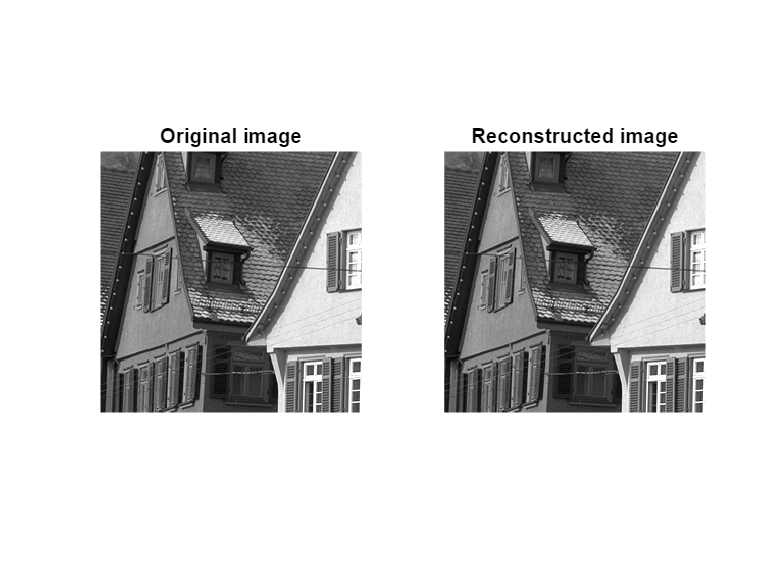

name = 'house';
u = load_image(name,[]);
n = length(u);

u1 = haar(u); % レベル1 HWT

j = log2(n)-1;
u1_LL = u1(1:2^j, 1:2^j);
u1_LH = u1(1:2^j, 2^j+1:2^(j+1));
u1_HL = u1(2^j+1:2^(j+1), 1:2^j);
u1_HH = u1(2^j+1:2^(j+1), 2^j+1:2^(j+1));

ur = ihaar(u1_LL,u1_LH,u1_HL,u1_HH);

% subplot(1,2,1);
% plot_wavelet(uw,J); title('Input HWT coef.');
% subplot(1,2,2);
% plot_wavelet(ur,j+1); title('IHWT result');

figure;
imageplot(u,'Original image',1,2,1);
imageplot(ur,'Reconstructed image',1,2,2);


disp(psnr(u, ur));

  316.0659



PSNRが300dB程度になっているので，（計算機誤差を除いて）完全に原信号が復元できていることがわかる．

## **演習問題**

**演習5**: グレースケール画像'house'を読み込み，レベル4のHWTの後に，レベル4のIHWTを計算し，復元した画像と原画像を並べて表示せよ．任意のレベル ($1,\dots, \log_2 N$) でHWTを可能にすれば加点する（画像の幅・高さは2のべき乗としてよい）．また，関数 `psnr` を用いて原画像と復元した画像間のPSNRを計算し，完全に復元できていることを確認せよ．

name = 'house';
u = load_image(name,[]);
n = length(u);

N = 2 %レベルの指定

N = 2

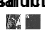

u1 = haar(u);
uh = u1;
for i = 1:N-1
    u_tmp = u1(1:n/(2^i), 1:n/(2^i));
    uh = u1;
    uh(1:n/(2^i), 1:n/(2^i)) = haar(u_tmp);
    u1 = uh;
end

figure;
imageplot(u,'Original image',1,2,1);
imageplot(uh,'Reconstructed image',1,2,2);

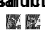


ur = uh;
i = N;
while i > 0
    u1_LL = ur(1:n/(2^i), 1:n/(2^i));
    u1_LH = ur(1:n/(2^i), n/(2^i)+1:n/(2^(i-1)));
    u1_HL = ur(n/(2^i)+1:n/(2^(i-1)), 1:n/(2^i));
    u1_HH = ur(n/(2^i)+1:n/(2^(i-1)), n/(2^i)+1:n/(2^(i-1)));

    ur(1:n/(2^(i-1)),1:n/(2^(i-1))) = ihaar(u1_LL,u1_LH,u1_HL,u1_HH);
    i = i-1;
end

figure;
imageplot(u,'Original image',1,2,1);
imageplot(ur,'Reconstructed image',1,2,2);


disp(psnr(u, ur));

  310.5027

